# Two-phase Flow Simulation with Viscous Fingering

clc
clear
close all

## Setting up model

#### Reservoir Geometry

Cell dimensions: $50\times 50\times 1$

Physical dimensions: $50\times 50\times 1$

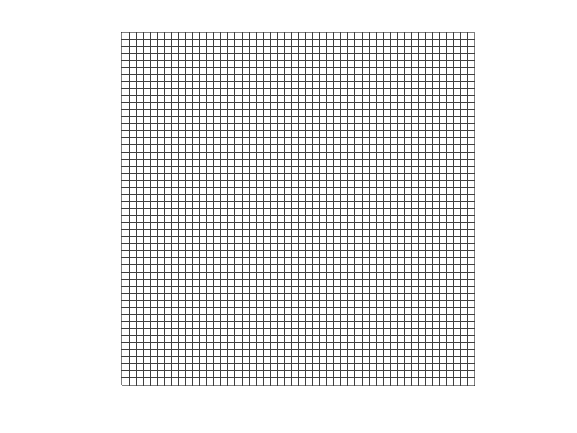

G = cartGrid([50,50,1]);
plotGrid(G,'FaceColor','none','EdgeAlpha',0.5)
axis equal
axis tight off

G = computeGeometry(G);

#### Rock properties

Heterogeneous anisotropic reservoir:                  

From SPE 10 data set

mrstModule add spe10
doprint = false;

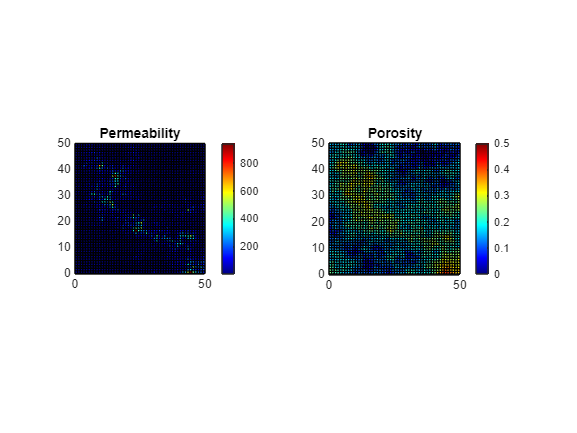

load spe10_rock.mat
roc = rock;
clear rock
A = zeros(50*50,2);
x = 1;
for i = 11:60
    for j = 121:170
        A(x,[1,2]) =  [i,j];
        x = x + 1;
    end
end
ind = sub2ind([60,220],A(:,1),A(:,2));
rock.perm = roc.perm(ind,:);
rock.poro = roc.poro(ind);
rock.poro(rock.poro == 0) = eps; 
hT = computeTrans(G,rock);
figure(1)
subplot(1,2,1)
plotCellData(G,convertTo(rock.perm(:,1),milli*darcy))
axis tight equal
colormap('jet')
colorbar
title('Permeability')
subplot(1,2,2)
plotCellData(G,rock.poro)
axis tight equal
colormap('jet')
colorbar
caxis([0,0.5])
title('Porosity')

## Fluid properties

## 
$$\mu_w =1\;\textrm{cP}\;\;\;\;\;\;\;\;\;\;\;\mu_o =\;5\;\textrm{cP}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\rho_w =1000\;\textrm{kg}/m^3 \;\;\;\;\;\;\;\;\;\;\rho_o =700\;\textrm{kg}/m^3$$


## Simplifed Brooks & Corey (Corey) model with exponent 2 and zero residual saturations:

## 
$$K_{\mathrm{rw}} ={S_w }^2 \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;K_{\mathrm{ro}} ={\left(1-S_w \right)}^2$$


mrstModule add incomp
fluid = initSimpleFluid('mu',[1 5],'rho',[1000 700],'n',[2 2]);
% fluid = initSimpleFluidJfunc('mu',[1,5]*centi*poise,'rho',[1000,700],'n',[2 2],'surf_tension',45*dyne/(centi*meter),'rock',rock);

# Injection time = 10 years

# Cumulative water injection = 1/3 PV

T = 10*year;
rate = sum(poreVolume(G,rock))/T/3;

## Well model

## Control type of injection & production well: rate

W = addWell([],G,rock,1,'Name','Injector','Type','rate','Val',rate,'Comp_i',[1 0]);
W = addWell(W,G,rock,G.cells.num,'Name','Producer','Type','rate','Val',-rate,'Comp_i',[0 1]);

Ignore capillary and gravity forces

state = initState(G,W,2000*psia,[0 1]);
ts_value = 50*day;
num_ts = T/ts_value;
time = 0;
h = figure(2);
for i = 1:num_ts
state = incompTPFA(state,G,hT,fluid,'Wells',W);
state = implicitTransport(state,G,ts_value,rock,fluid,'Wells',W);

#### Plotting results

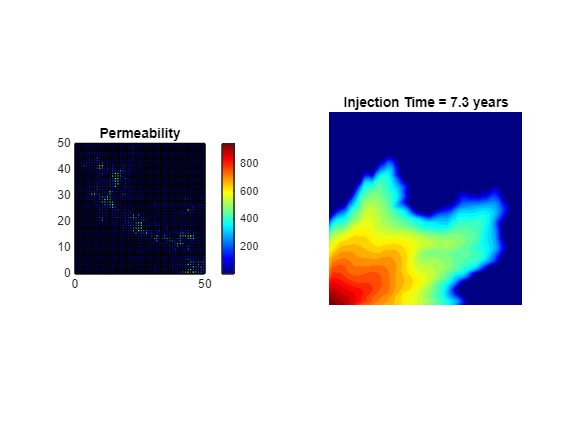

Error using colormap (line 61)
First argument must be a scalar axes or figure handle.

x = G.cells.centroids(:,1);
y = G.cells.centroids(:,2);
X = reshape(x, G.cartDims);
Y = reshape(y, G.cartDims);
Z = reshape(state.s(:,1),G.cartDims);
contourf(X,Y,Z,30, 'EdgeColor','none');
time = time + ts_value;
title(sprintf('Injection Time = %.1f years',convertTo(time,year)))
axis tight off
axis equal
cmap = colormap(h,flipud(jet(30)));
cmap(1,:) = [0.1, 0.01, 0.01];
colormap(h,cmap)
colorbar
caxis([0,1])
pause(0.5)
end